% Different motions / manipulation actions lead to different kinds of haptic data.
% We are only going to look at the Hold action and only six objects

% preasure: pdc
% vibation: pac
% temperature: tdc
% temperature change: tac

% 1.acrylic (一种化学材料)
% 2.black_foam (黑色泡沫)
% 3.car_sponge (洗车海绵)
% 4.flour_sack (面粉袋)
% 5.kitchen_sponge (厨房海绵)
% 6.steel_vase (铁瓶)

clc;clear;
folderPath = './PR_CW_DATA_2021'; 
filePattern = fullfile(folderPath, '*.mat');
matFiles = dir(filePattern);

for k = 1:length(matFiles)
    baseFileName = matFiles(k).name;
    fullFileName = fullfile(folderPath, baseFileName);
    [~, baseFileName, ~] = fileparts(fullFileName);
    s = load(fullFileName);
    eval([baseFileName ' = s;']);
end
black_foam_110_08_HOLD = pre_process(black_foam_110_08_HOLD);

acrylic = import_data('acrylic');
black_foam = import_data('black_foam');
car_sponge = import_data('car_sponge');
flour_sack  = import_data('flour_sack');
kitchen_sponge = import_data('kitchen_sponge');
steel_vase = import_data('steel_vase');
%-----------------------------------------------------------%
% example: visit object , finger 0 --> preasure(pdc) --> measure 1
black_foam.F0pdc(1,:);

% example: visit object ,  finger 0 --> vibation(pac) --> measure 1
black_foam.F0pac{1};

% plot(black_foam.F0pac{1}');

### **Section A: 准备数据集**

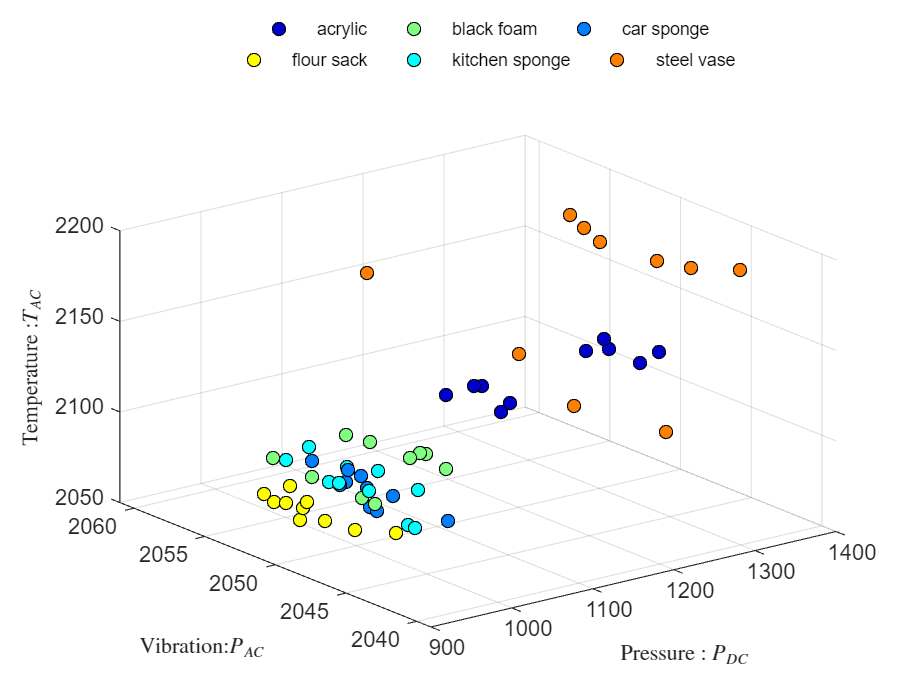

% Finger F0
% Create dataset F0_PVT
F0_PVT = [];
objects = {acrylic, black_foam,car_sponge,flour_sack,kitchen_sponge,steel_vase}; 

PVT_data = cell(length(objects), 1);

% Define colors for the objects
colors = {[0,0,0.8], [0.0, 0.5019607843137255, 1.0],[0.0, 1.0, 1.0],
            [0.5019607843137255, 1.0, 0.5019607843137255],[1.0, 1.0, 0.0],[1.0, 0.5019607843137255, 0.0]}; 

h = []; % 画图句柄
for i = 1:length(objects)
    
    PVT_data{i} = samplePVT(objects{i});
    
    % 同时构建 F0_PVT 数据集
    F0_PVT = [F0_PVT; PVT_data{i}];
    ht = scatter3(PVT_data{i}(:,1), PVT_data{i}(:,2), PVT_data{i}(:,3), ...
                'MarkerEdgeColor','k',...
                'MarkerFaceColor',cell2mat(colors(i)));
    h = [h ht];
    hold on;
end
xlabel('Pressure : $P_{DC}$', 'Interpreter', 'latex', 'FontSize', 10);
ylabel('Vibration:$P_{AC}$','Interpreter','latex','FontSize', 10);
zlabel('Temperature :$T_{AC}$','Interpreter','latex','FontSize', 10);


l2 = legend([h(4),h(5),h(6)],'flour sack','kitchen sponge','steel vase');
set(l2,'Orientation','horizon','Box','off');
set(l2,'Location','Northoutside','FontSize',8);
ah = axes('Position',get(l2,'position'),'Visible','off');

l1 = legend(ah,[h(1),h(2),h(3)],'acrylic','black foam','car sponge');
set(l1,'Orientation','horizon','Box','off');
set(l1,'Location','Northoutside','FontSize',8);

hold off;
exportgraphics(gcf,'./figures/3D_scatter_plot_PVT.png','Resolution',600);

% Create dataset F0_Electrodes
F0_Electrodes = [];
objects = {acrylic, black_foam,car_sponge,flour_sack,kitchen_sponge,steel_vase}; 


% 构建 F0_Electrodes 数据集
for i = 1:length(objects)
    
    Electrodes_data = sampleElectrode(objects{i});
    
    F0_Electrodes = [F0_Electrodes; Electrodes_data];
end

% size(F0_Electrodes)

save('./F0_Electrodes.mat', 'F0_Electrodes');
save('./F0_PVT.mat', 'F0_PVT');



## Section B: 对 PVT data PCA

[n,~] = size(F0_PVT);

% step1: Standardise the data
% compute the mean of the data matrix
x_bar = 1/n * F0_PVT' * ones(n,1);

% substract the mean 
global m
[m,~] = size(F0_PVT);
F0_PVT_Standardised = F0_PVT - ones(m,1) * x_bar';


% step 2: compute the covariance matrix of the standardised data

% S = 1/n * F0_PVT'*(eye(n)-1/n*ones(n,1)*ones(n,1)')*F0_PVT
S = 1/n * F0_PVT_Standardised'*(eye(n)-1/n*ones(n,1)*ones(n,1)')*F0_PVT_Standardised

S = 1.0e+04 *

    1.3625   -0.0144    0.3982
   -0.0144    0.0015   -0.0057
    0.3982   -0.0057    0.1481



% Eigenvalue and eigen vector 分解 S
[F,V] = eig(S);

eigenvectors = F

eigenvectors =     0.9581   -0.2863   -0.0039
   -0.0104   -0.0486    0.9988
    0.2862    0.9569    0.0495


eigenvalues = sum(V)

eigenvalues = 1.0e+04 *

    1.4815    0.0292    0.0012



% [P,scrs,~,~,pexp] = pca(F0_PVT); % matlab built-in PCA
% plot the standardised data
figure
for i = 1:6
    if i == 1
        scatter3(F0_PVT_Standardised(1:(m/6),1),F0_PVT_Standardised(1:(m/6),2), F0_PVT_Standardised(1:(m/6),3), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor',cell2mat(colors(i)));
        hold on
    else
        scatter3(F0_PVT_Standardised((m/6)*(i-1)+1:(m/6)*i,1), ...
            F0_PVT_Standardised((m/6)*(i-1)+1:(m/6)*i,2), ...
            F0_PVT_Standardised((m/6)*(i-1)+1:(m/6)*i,3), ...
            'MarkerEdgeColor','k',...
                'MarkerFaceColor',cell2mat(colors(i)));
        hold on
    end
end
xlabel('Preasure : $P_{DC}$','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
ylabel('Vibration:$P_{AC}$','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
zlabel('Temperature :$T_{AC}$','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');


% plot the eigenvectors
a = 60 ; % scaling factor of the eigenvector
v1 = vector([0 0 0], a*F(:,1)', SphereDiameter=5,ConeWidth=5 ,ShaftWidth =1.5);

vectorupdate(v1,Color=[1 0 0]); % r

v2 = vector([0 0 0], a*F(:,2)', SphereDiameter=5,ConeWidth=5,ShaftWidth =1.5);

vectorupdate(v2,Color=[1 0 0]);

v3 = vector([0 0 0], a*F(:,3)', SphereDiameter=5,ConeWidth=5,ShaftWidth =1.5);

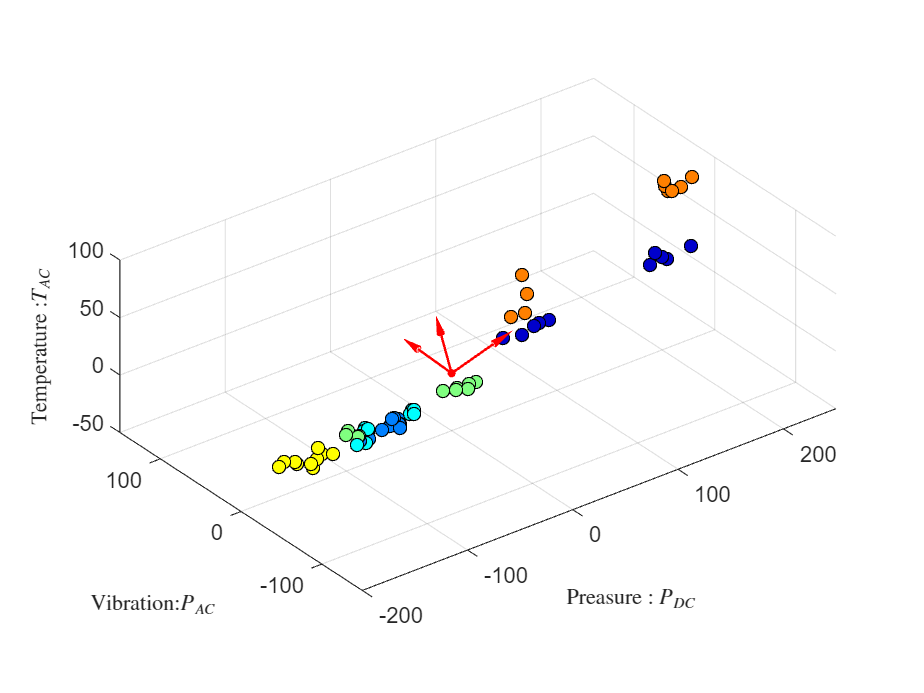

vectorupdate(v3,Color=[1 0 0]);
ylim([-150,150])
% view(-40,20);
% hold off
exportgraphics(gcf,'./figures/Standardised_data_with_PCS.png','Resolution',600);

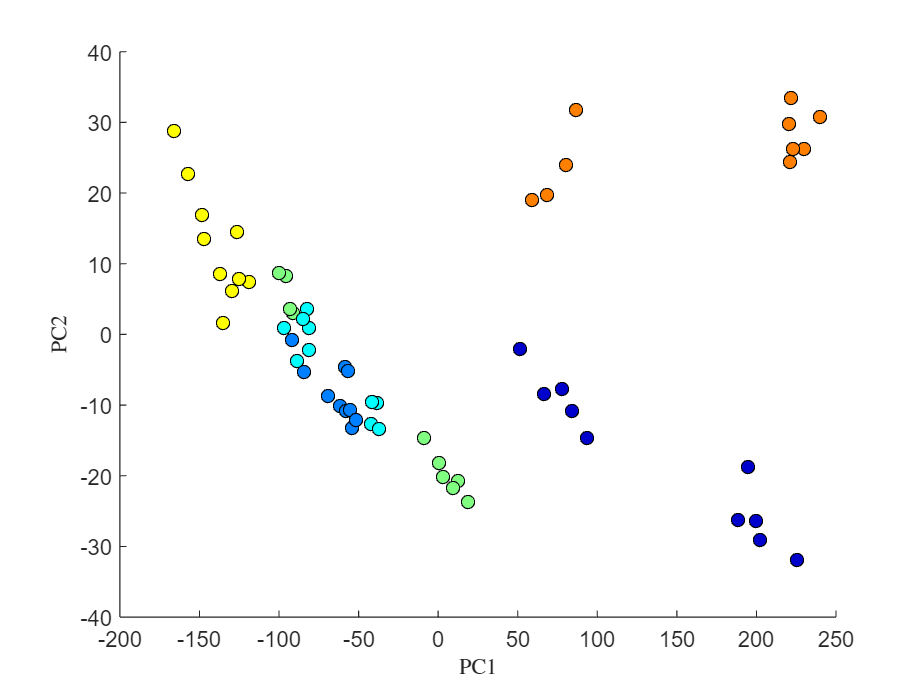

% Reduce the data to 2-dimensions and replot.
feature_vector = [F(:,1) F(:,2)];
projected_PVT = F0_PVT_Standardised *feature_vector;

% plot the 2D projected standardised data
figure
for i = 1:6
    if i == 1
        scatter(projected_PVT(1:(m/6),1),projected_PVT(1:(m/6),2), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor',cell2mat(colors(i)));
        hold on
    else
        scatter(projected_PVT((m/6)*(i-1)+1:(m/6)*i,1), ...
            projected_PVT((m/6)*(i-1)+1:(m/6)*i,2), ...
            'MarkerEdgeColor','k',...
                'MarkerFaceColor',cell2mat(colors(i)));
        hold on
    end
end
xlabel('PC1','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
ylabel('PC2','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
exportgraphics(gcf,'./figures/projected_to_2D_PVT.png','Resolution',600);

% 投影到每一个 PC 线上
PC1 = F(:,1);
PC2 = F(:,2);
PC3 = F(:,3);

projected_PVT_PC1 = F0_PVT_Standardised *PC1;
projected_PVT_PC2 = F0_PVT_Standardised *PC2;
projected_PVT_PC3 = F0_PVT_Standardised *PC3;

figure

plot_1D(projected_PVT_PC1,-2.5)
hold on
plot_1D(projected_PVT_PC2,-2)
hold on
plot_1D(projected_PVT_PC3,-1.5)
ylim([-3,-1.2]);
grid on;
set(gca, 'YTick');

  空的 0×0 cell 数组



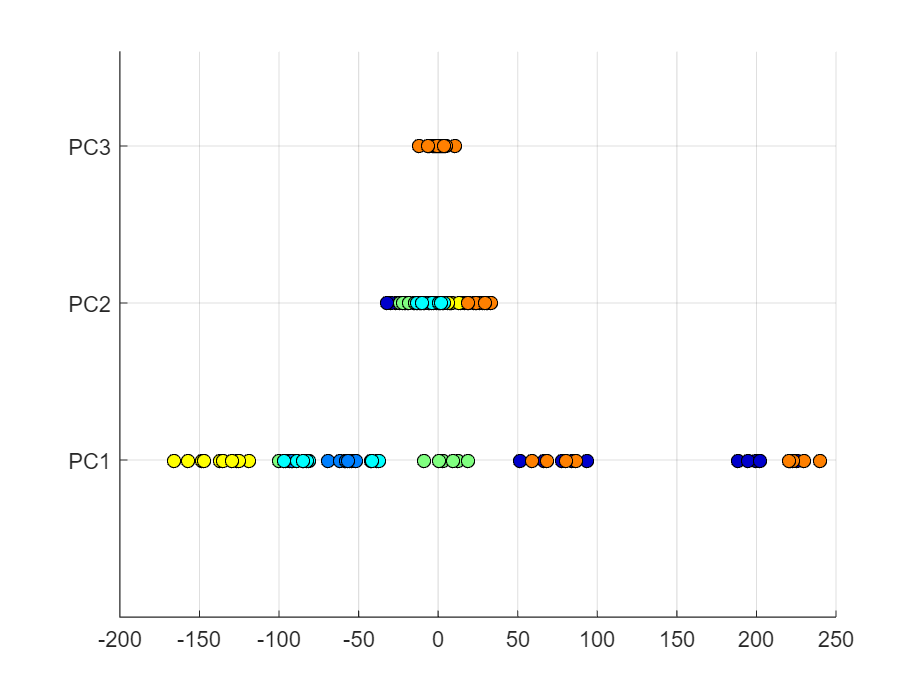

set(gca, 'YTick', [-2.5 -2 -1.5]);
set(gca, 'YTickLabel', {'PC1', 'PC2', 'PC3'});hold off
exportgraphics(gcf,'./figures/projected_to_1D_PVT.png','Resolution',600);
hold off

## Section B: 对 electrode data PCA

global n

[n,~] = size(F0_Electrodes);

% step1: Standardise the data
% compute the mean of the data matrix
F0_Electrodes_bar = 1/n * F0_Electrodes' * ones(n,1);

% substract the mean 
F0_Electrodes_Standardised = F0_Electrodes - ones(n,1) * F0_Electrodes_bar';

% step 2: compute the covariance matrix of the standardised data
S_E = 1/n * F0_Electrodes_Standardised'*(eye(n)-1/n*ones(n,1)*ones(n,1)')*F0_Electrodes_Standardised;

% Eigenvalue and eigen vector 分解 S_E
[F_E,V_E,~] = svd(S_E); % 等效于 eig()

% 不用 eig 了, 没有排序
% [F_E,V_E] = eig(S_E);
% F_E = real(F_E)

VE = sum(V_E)

VE = 1.0e+04 *

    9.0659    0.5337    0.0513    0.0291    0.0187    0.0097    0.0050    0.0016    0.0011    0.0004    0.0002    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000


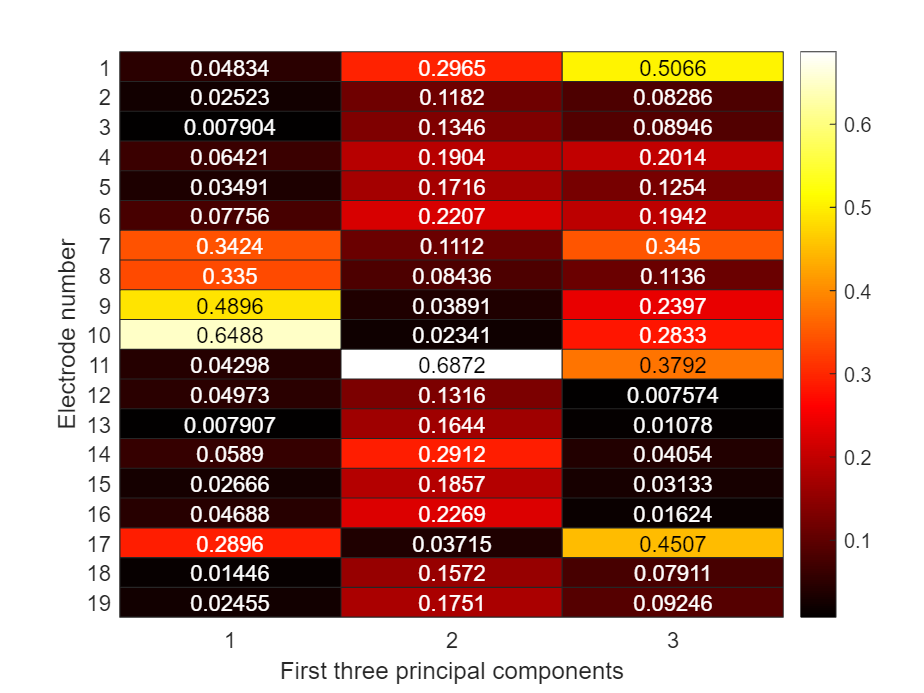


feature_v = [F_E(:,1) F_E(:,2) F_E(:,3)];% 7 8 9 10 17

figure
% 特征贡献
varnames = arrayfun(@(x) sprintf('%d', x), 1:19, 'UniformOutput', false);
h= heatmap(abs(feature_v),...
     "YDisplayLabels",varnames);

% Set the colormap to 'hot' (or you can customize it further if needed)
colormap(h, 'hot');
xlabel("First three principal components")
ylabel("Electrode number")
exportgraphics(gcf,'./figures/electrode_feature_contribution.png','Resolution',600);

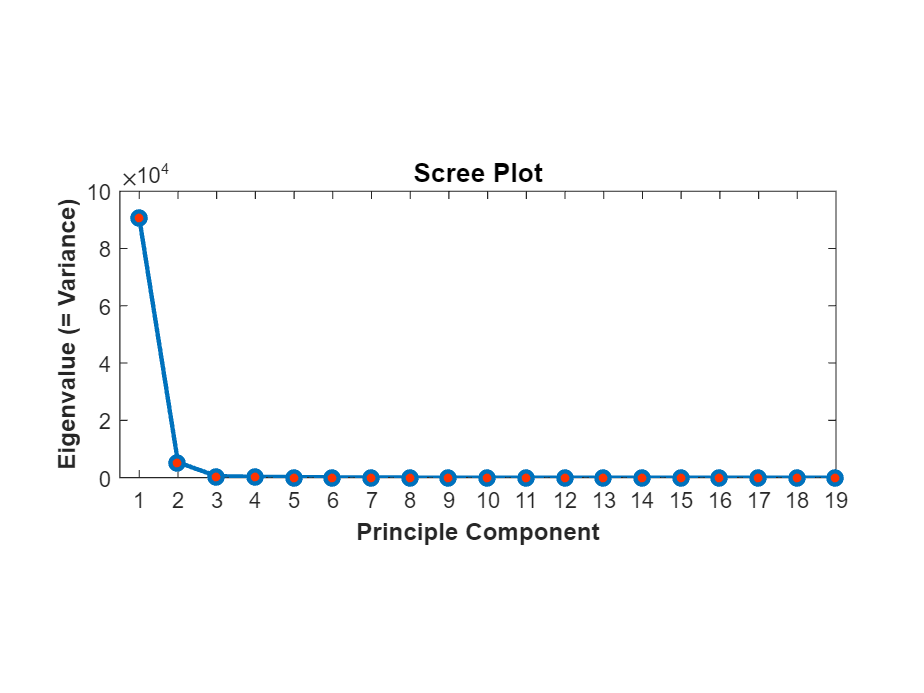





% plot the scree plot
figure
p = plot([1:19],VE,'-o','LineWidth',2);
p.MarkerFaceColor = [1 0.2 0];
title("Scree Plot",'fontweight','bold','fontsize',12);
xticks(1:19);xtickangle(0);xlim([0.5,19]);
xlabel("Principle Component",'fontweight','bold')
ylabel("Eigenvalue (= Variance)",'fontweight','bold')
pbaspect([2.5 1 1]); 
exportgraphics(gcf,'./figures/scree_plot.png','Resolution',600);

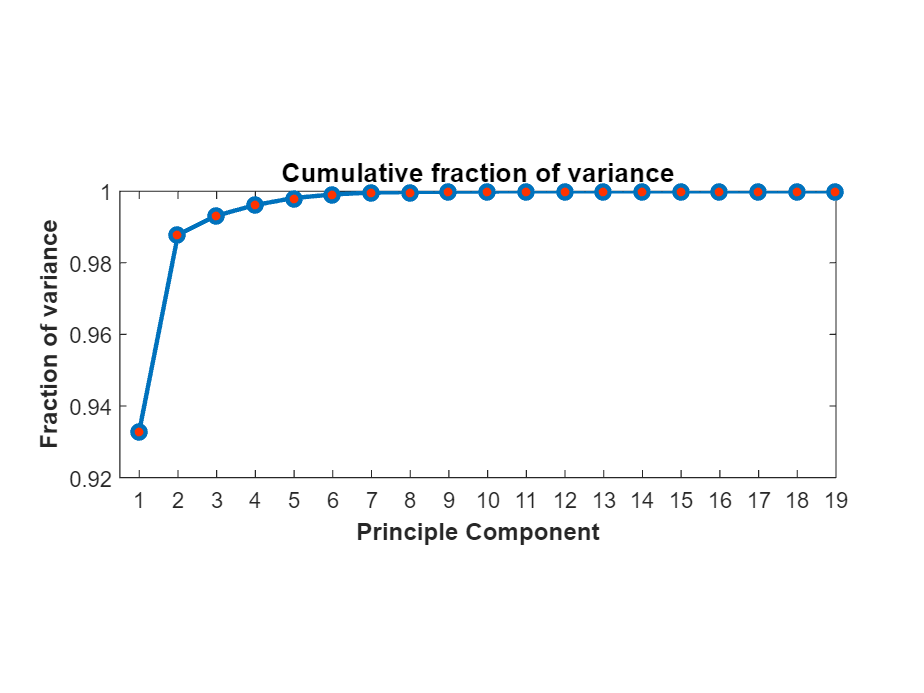


% plot the cum scree plot 
figure
p = plot([1:19],cumsum(VE/sum(VE)),'-o','LineWidth',2);
p.MarkerFaceColor = [1 0.2 0];
xticks(1:19);xtickangle(0);xlim([0.5,19]);
title("Cumulative fraction of variance",'fontweight','bold','fontsize',12);
xlabel("Principle Component",'fontweight','bold')
ylabel("Fraction of variance",'fontweight','bold')
pbaspect([2.5 1 1]); 
exportgraphics(gcf,'./figures/scree_plot_cum.png','Resolution',600);

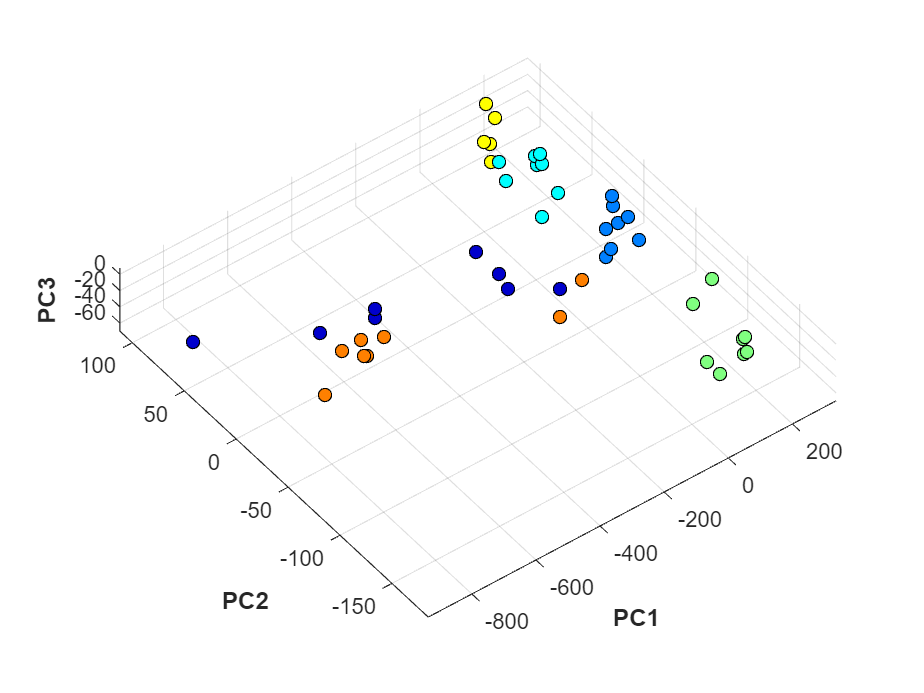



% % plot the scree plot in log scale
% figure
% p = plot([1:19],log(VE),'-o','LineWidth',2);
% p.MarkerFaceColor = [1 0.2 0];
% title("Scree Plot in log scale",'fontweight','bold','fontsize',12);
% xticks(1:19);xtickangle(0);xlim([0.5,19]);
% xlabel("Principle Component",'fontweight','bold')
% ylabel("Eigenvalue (= Variance)",'fontweight','bold')
% exportgraphics(gcf,'./figures/scree_plot_log_scale.png','Resolution',600);




projected_ele = F0_Electrodes_Standardised * feature_v;

% plot the 3D projected standardised data
figure
for i = 1:6
    if i == 1
        scatter3(projected_ele(1:(m/6),1),projected_ele(1:(m/6),2), ...
            projected_ele(1:(m/6),3), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor',cell2mat(colors(i)));
        hold on
    else
        scatter3(projected_ele((m/6)*(i-1)+1:(m/6)*i,1), ...
            projected_ele((m/6)*(i-1)+1:(m/6)*i,2), ...
            projected_ele(1:(m/6),3),...
            'MarkerEdgeColor','k',...
                'MarkerFaceColor',cell2mat(colors(i)));
        hold on
    end
end

xlabel("PC1",'fontweight','bold')
ylabel("PC2",'fontweight','bold')
zlabel("PC3",'fontweight','bold')

xlim([-936 336])
ylim([-185 112])
zlim([-69.9 7.8])
view([-37.1 80.0])
exportgraphics(gcf,'./figures/electrode_data_projected.png','Resolution',600);

## Section C: LDA

We want to see if we can discriminate two deformable and porous objects by touch: the black foam(class-2) and the car sponge(class-3)

Note: I use *patch()* to plot a plane in Matlab, with the *FaceAlpha*property set to 0.5 to enable transparency

[bc_projected_PV,a,b,v1] = LDA_on_two_object(objects{2},objects{3},1,2);

V =    -1.0000   -0.0080
   -0.0080    1.0000


J =     0.0298         0
         0    6.8424


[bc_projected_PT,c,d,v2] = LDA_on_two_object(objects{2},objects{3},1,3);

V =    -0.9992   -0.0406
   -0.0406    0.9992


J =     0.0316         0
         0   10.7003


[bc_projected_VT,e,f,v3] = LDA_on_two_object(objects{2},objects{3},2,3);

V =    -0.6875   -0.7262
   -0.7262    0.6875


J =     0.3113         0
         0    0.6819


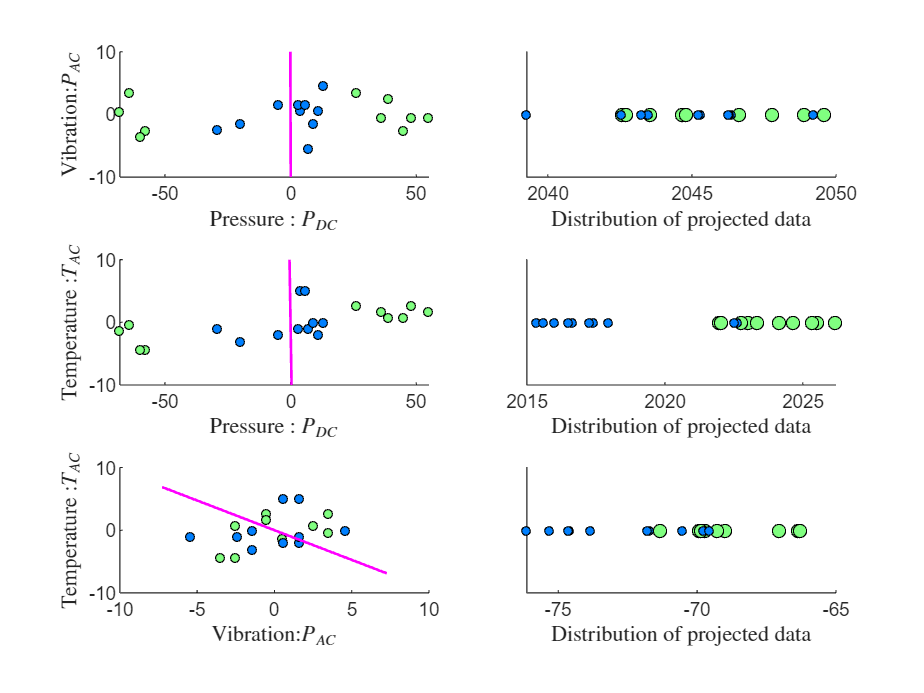


n_fig = 3;
figure
subplot(n_fig,2,1)
scatter(a(1:10),a(11:20),16, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(2)))
hold on
scatter(b(1:10),b(11:20),16,...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(3)))
hold on
plot([0, 10*v1(1)], [0, 10*v1(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
plot([0, -10*v1(1)], [0, -10*v1(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
xlabel('Pressure : $P_{DC}$', 'Interpreter', 'latex', 'FontSize', 10);
ylabel('Vibration:$P_{AC}$','Interpreter','latex','FontSize', 10);




subplot(n_fig,2,3)
scatter(c(1:10),c(11:20),16, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(2)))
hold on
scatter(d(1:10),d(11:20),16, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(3)))
hold on
plot([0, 10*v2(1)], [0, 10*v2(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
plot([0, -10*v2(1)], [0, -10*v2(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
xlabel('Pressure : $P_{DC}$', 'Interpreter', 'latex', 'FontSize', 10);
ylabel('Temperature :$T_{AC}$','Interpreter','latex','FontSize', 10);

subplot(n_fig,2,5)

scatter(e(1:10),e(11:20),16, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(2)))
hold on
scatter(f(1:10),f(11:20),16, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(3)))
hold on
plot([0, 10*v3(1)], [0, 10*v3(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
plot([0, -10*v3(1)], [0, -10*v3(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
xlabel('Vibration:$P_{AC}$','Interpreter','latex','FontSize', 10);
ylabel('Temperature :$T_{AC}$','Interpreter','latex','FontSize', 10);

% ----------------------------------------------%
subplot(n_fig,2,2)
scatter(bc_projected_PV(1:10),0*ones(10,1), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(2)))
hold on
scatter(bc_projected_PV(11:20),0*ones(10,1),15, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(3)))
yticks([]); xlabel('Distribution of projected data','Interpreter','latex','FontSize', 10)


subplot(n_fig,2,4)
scatter(bc_projected_PT(1:10),1*ones(10,1), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(2)))
hold on
scatter(bc_projected_PT(11:20),1*ones(10,1),15, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(3)))
yticks([]); xlabel('Distribution of projected data','Interpreter','latex','FontSize', 10)

subplot(n_fig,2,6)
scatter(bc_projected_VT(1:10),1*ones(10,1), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(2)))
hold on
scatter(bc_projected_VT(11:20),1*ones(10,1),15, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(3)))
yticks([]); xlabel('Distribution of projected data','Interpreter','latex','FontSize', 10)

exportgraphics(gcf,'./figures/LDA_feature_pairs.png','Resolution',600);

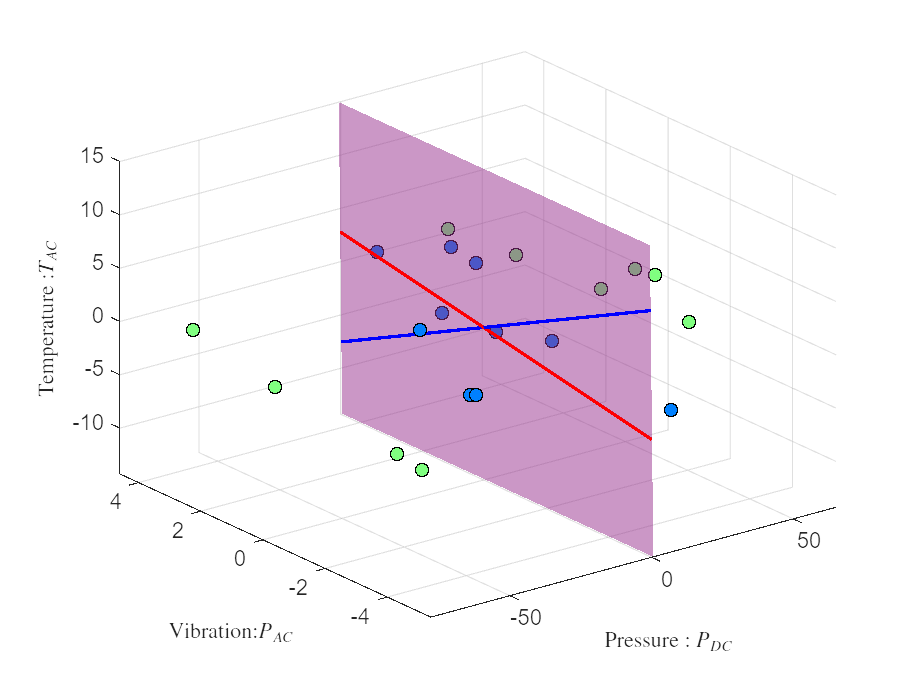

% 3D LDA
% PVT 差异最大的两类物体: 1,4 
c1 = samplePVT(objects{2});
c2 = samplePVT(objects{3});
[n1,~] = size(c1);
[n2,~] = size(c2);

mu_1 = mean(c1); mu_2 = mean(c2);
% standarized the data
c1 = c1 - mu_1; c2 = c2 - mu_2;
s1 = (n1-1) .* cov(c1); s2 = (n2-1) .* cov(c2);
SB = (mu_1 - mu_2)*(mu_1 - mu_2)';
SW = s1 + s2;

M = inv(SW)  * SB;
[V, J]= eig(M);

v = [V(:,2),V(:,3)];

projected_PVT = [c1+mu_1;c2+mu_2] * v;

% plot 投影之前的 data
figure
scatter3(c1(:,1),c1(:,2),c1(:,3), ...
            'MarkerEdgeColor', 'k',...
            'MarkerFaceColor', cell2mat(colors(2)))
hold on
scatter3(c2(:,1),c2(:,2),c2(:,3), ...
            'MarkerEdgeColor', 'k',...
            'MarkerFaceColor', cell2mat(colors(3)))
plot_2D_projection_plane(c1,c2,v);
xlabel('Pressure : $P_{DC}$', 'Interpreter', 'latex', 'FontSize', 10, 'FontWeight', 'bold');
ylabel('Vibration:$P_{AC}$','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
zlabel('Temperature :$T_{AC}$','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
exportgraphics(gcf,'./figures/LDA_PVT_3D.png','Resolution',600);

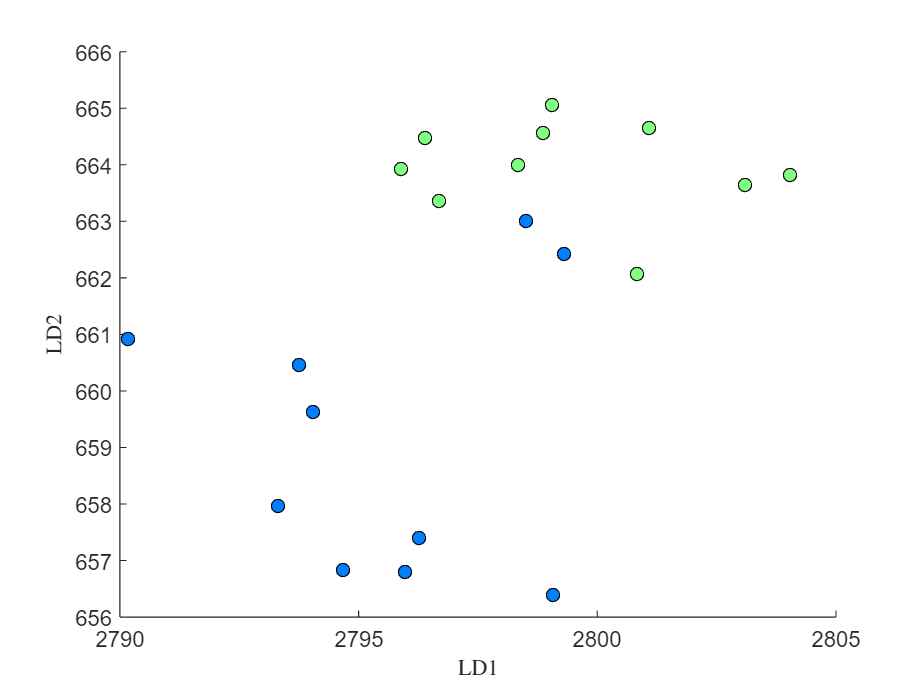




% 2D 投影之后的
figure
scatter(projected_PVT(1:10,1),projected_PVT(1:10,2), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(2)))

hold on
scatter(projected_PVT(11:20,1),projected_PVT(11:20,2), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(3)))
xlabel('LD1','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
ylabel('LD2','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
exportgraphics(gcf,'./figures/LDA_PVT_2D_projected.png','Resolution',600);

## My choice of objects

idx1 = 1;
idx2 = 4;
[bc_projected_PV,a,b,v1] = LDA_on_two_object(objects{idx1},objects{idx2},1,2);

V =    -0.9998    0.0173
    0.0173    0.9998


J =     1.6844         0
         0  878.3513


[bc_projected_PT,c,d,v2] = LDA_on_two_object(objects{idx1},objects{idx2},1,3);

V =    -0.9914   -0.1311
   -0.1311    0.9914


J =     1.7118         0
         0  172.0642


[bc_projected_VT,e,f,v3] = LDA_on_two_object(objects{idx1},objects{idx2},2,3);

V =     0.1278   -0.9918
   -0.9918   -0.1278


J =     2.0314         0
         0   31.5465


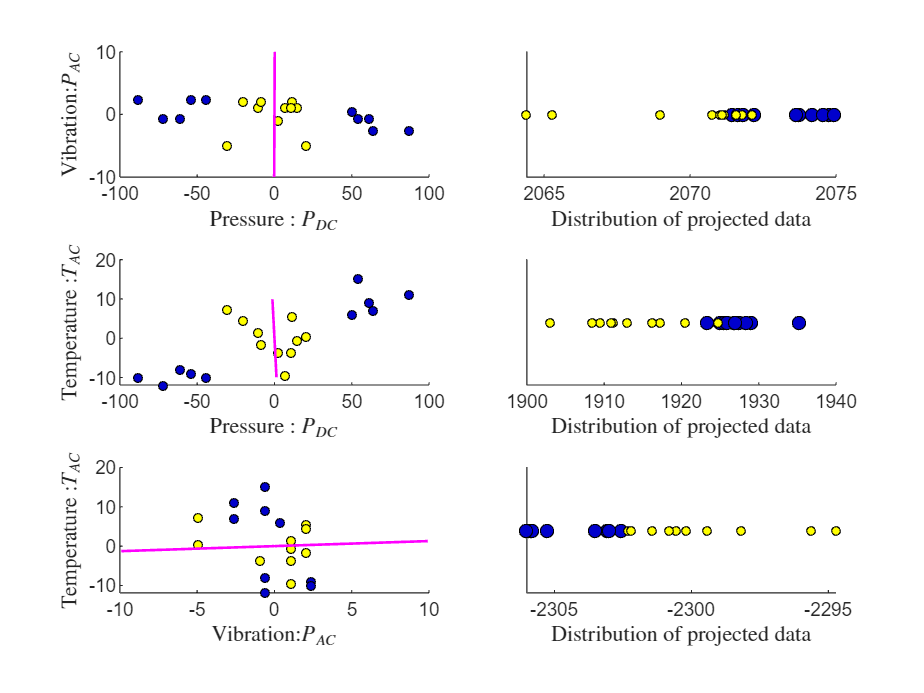


n_fig = 3;
figure
subplot(n_fig,2,1)
scatter(a(1:10),a(11:20),16, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx1)))
hold on
scatter(b(1:10),b(11:20),16,...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx2)))
hold on
plot([0, 10*v1(1)], [0, 10*v1(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
plot([0, -10*v1(1)], [0, -10*v1(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
xlabel('Pressure : $P_{DC}$', 'Interpreter', 'latex', 'FontSize', 10);
ylabel('Vibration:$P_{AC}$','Interpreter','latex','FontSize', 10);




subplot(n_fig,2,3)
scatter(c(1:10),c(11:20),16, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx1)))
hold on
scatter(d(1:10),d(11:20),16, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx2)))
hold on
plot([0, 10*v2(1)], [0, 10*v2(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
plot([0, -10*v2(1)], [0, -10*v2(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
xlabel('Pressure : $P_{DC}$', 'Interpreter', 'latex', 'FontSize', 10);
ylabel('Temperature :$T_{AC}$','Interpreter','latex','FontSize', 10);

subplot(n_fig,2,5)

scatter(e(1:10),e(11:20),16, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx1)))
hold on
scatter(f(1:10),f(11:20),16, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx2)))
hold on
plot([0, 10*v3(1)], [0, 10*v3(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
plot([0, -10*v3(1)], [0, -10*v3(2)], 'm-',LineWidth=1.2); % 'b-' 指定为蓝色实线
xlabel('Vibration:$P_{AC}$','Interpreter','latex','FontSize', 10);
ylabel('Temperature :$T_{AC}$','Interpreter','latex','FontSize', 10);

% ----------------------------------------------%
subplot(n_fig,2,2)
scatter(bc_projected_PV(1:10),0*ones(10,1), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx1)))
hold on
scatter(bc_projected_PV(11:20),0*ones(10,1),15, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx2)))
yticks([]); xlabel('Distribution of projected data','Interpreter','latex','FontSize', 10)


subplot(n_fig,2,4)
scatter(bc_projected_PT(1:10),1*ones(10,1), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx1)))
hold on
scatter(bc_projected_PT(11:20),1*ones(10,1),15, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx2)))
yticks([]); xlabel('Distribution of projected data','Interpreter','latex','FontSize', 10)

subplot(n_fig,2,6)
scatter(bc_projected_VT(1:10),1*ones(10,1), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx1)))
hold on
scatter(bc_projected_VT(11:20),1*ones(10,1),15, ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(idx2)))
yticks([]); xlabel('Distribution of projected data','Interpreter','latex','FontSize', 10)

exportgraphics(gcf,'./figures/LDA_feature_pairs_my_objects.png','Resolution',600);

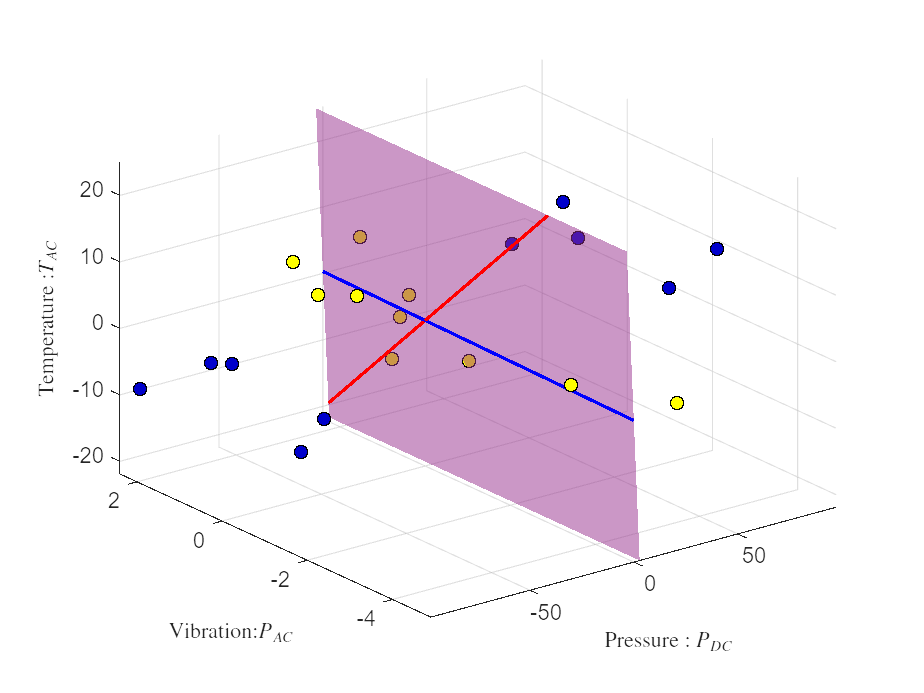

% 3D LDA
% PVT 差异最大的两类物体: 1,4 
c1 = samplePVT(objects{1});
c2 = samplePVT(objects{4});
[n1,~] = size(c1);
[n2,~] = size(c2);

mu_1 = mean(c1); mu_2 = mean(c2);
% standarized the data
c1 = c1 - mu_1; c2 = c2 - mu_2;
s1 = (n1-1) .* cov(c1); s2 = (n2-1) .* cov(c2);
SB = (mu_1 - mu_2)*(mu_1 - mu_2)';
SW = s1 + s2;

M = inv(SW)  * SB;
[V, J]= eig(M);

v = [V(:,2),V(:,3)];

projected_PVT = [c1+mu_1;c2+mu_2] * v;

% plot 投影之前的 data
figure
scatter3(c1(:,1),c1(:,2),c1(:,3), ...
            'MarkerEdgeColor', 'k',...
            'MarkerFaceColor', cell2mat(colors(1)))
hold on
scatter3(c2(:,1),c2(:,2),c2(:,3), ...
            'MarkerEdgeColor', 'k',...
            'MarkerFaceColor', cell2mat(colors(4)))
plot_2D_projection_plane(c1,c2,v);
xlabel('Pressure : $P_{DC}$', 'Interpreter', 'latex', 'FontSize', 10, 'FontWeight', 'bold');
ylabel('Vibration:$P_{AC}$','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
zlabel('Temperature :$T_{AC}$','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
exportgraphics(gcf,'./figures/LDA_PVT_3D_my_object.png','Resolution',600);

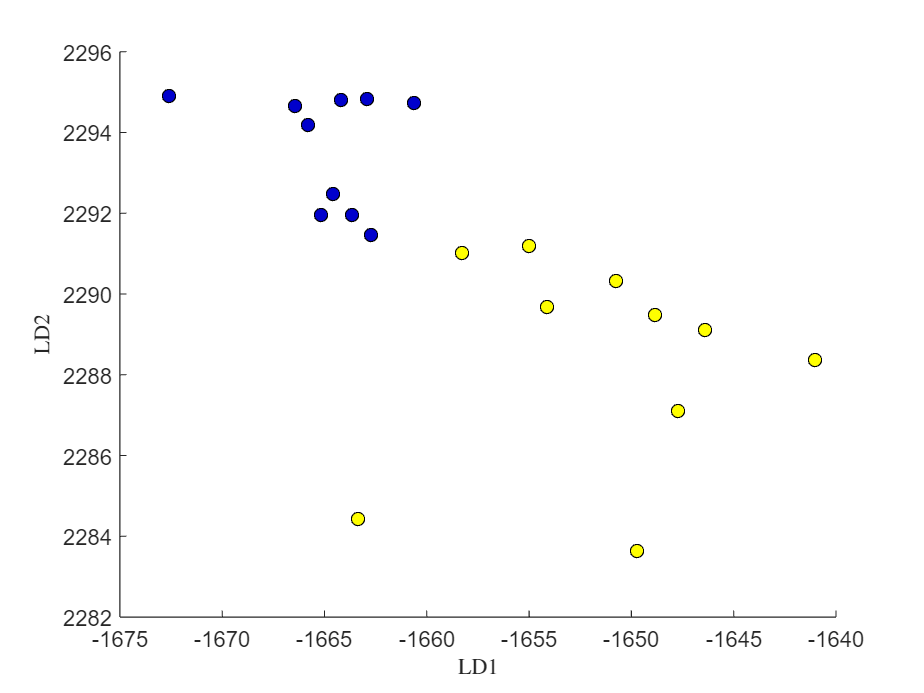




% 2D 投影之后的
figure
scatter(projected_PVT(1:10,1),projected_PVT(1:10,2), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(1)))

hold on
scatter(projected_PVT(11:20,1),projected_PVT(11:20,2), ...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor', cell2mat(colors(4)))
xlabel('LD1','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
ylabel('LD2','Interpreter','latex','FontSize', 10, 'FontWeight', 'bold');
exportgraphics(gcf,'./figures/LDA_PVT_2D_projected_my_object.png','Resolution',600);

## **Section D: Clustering & Classification**

This isn't a particularly good grouping. Try changing the `"Distance"` property and see how it impacts the groups. Can you get a better grouping by changing some of the properties?

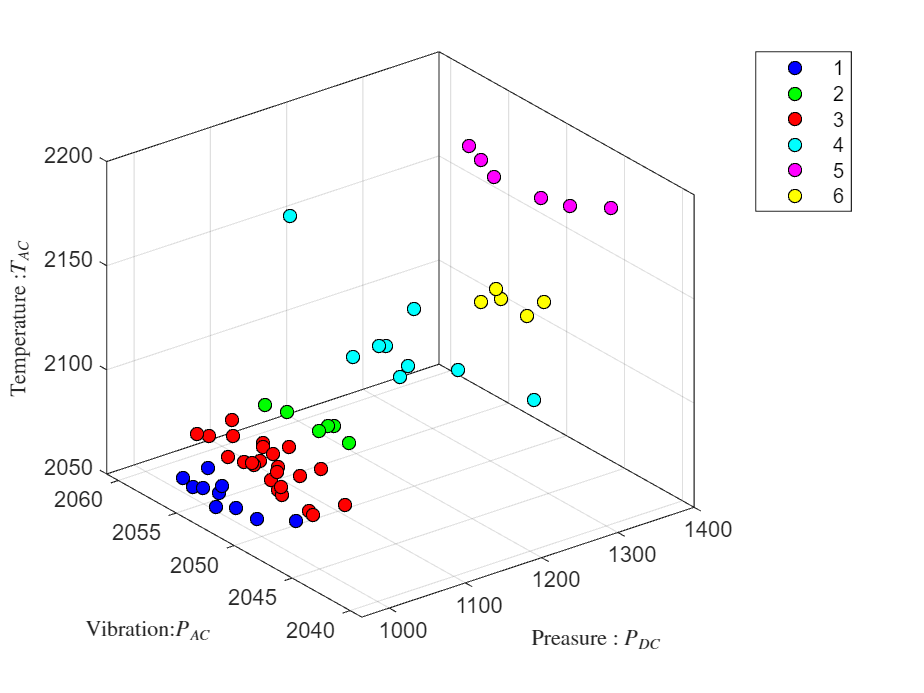

% Use the kmeans function to perform k-means clustering
k = 6; % number of clusters
% grp: a vector of corresponding group number
% C: centroids of each group
% Distance: 'sqeuclidean','cosine','cityblock','correlation'	
labels = {'acrylic', 'black foam', 'car sponge', 'flour sack', 'kitchen sponge', 'steel vase'};
repeatedLabels = repmat(labels, 10, 1);
repeatedLabels = repeatedLabels(:); % Convert from matrix to vector
yCat = categorical(repeatedLabels);

[grp,C] = kmeans(F0_PVT,k,"Distance",'sqeuclidean',...
        "Start","cluster","Replicates",55); 

%  Visualize the groups by viewing the data in a scatter plot 
%  and assigning each group a different color
figure
gscatter3(F0_PVT(:,1),F0_PVT(:,2),F0_PVT(:,3),grp)
xlabel('Preasure : $P_{DC}$','Interpreter','latex',FontSize=10);
ylabel('Vibration:$P_{AC}$','Interpreter','latex',FontSize=10);
zlabel('Temperature :$T_{AC}$','Interpreter','latex',FontSize=10);
exportgraphics(gcf,'./figures/visualize_kmeans_sqeuclidean.png','Resolution',300)

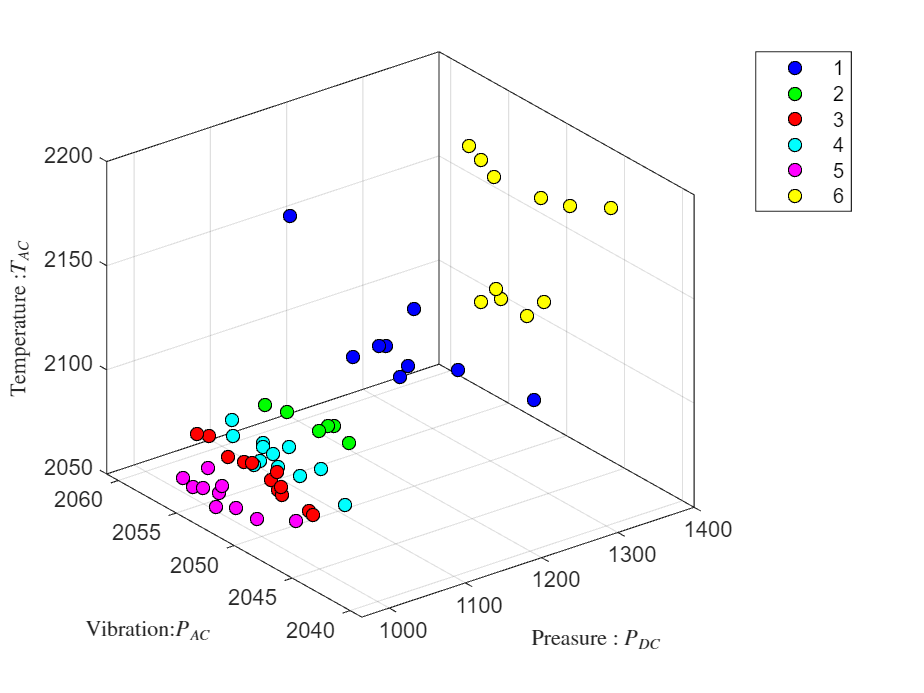

% cts = crosstab(yCat,grp);
% heatmap(cts,"YDisplayLabels",categories(yCat))


% Use the kmeans function to perform k-means clustering
k = 6; % number of clusters	
[grp,C] = kmeans(F0_PVT,k,"Distance",'cosine',...
        "Start","cluster","Replicates",55); 

%  Visualize the groups by viewing the data in a scatter plot 
%  and assigning each group a different color
figure
gscatter3(F0_PVT(:,1),F0_PVT(:,2),F0_PVT(:,3),grp)
xlabel('Preasure : $P_{DC}$','Interpreter','latex',FontSize=10);
ylabel('Vibration:$P_{AC}$','Interpreter','latex',FontSize=10);
zlabel('Temperature :$T_{AC}$','Interpreter','latex',FontSize=10);
exportgraphics(gcf,'./figures/visualize_kmeans_cosine.png','Resolution',300)

% cts = crosstab(yCat,grp);
% heatmap(cts,"YDisplayLabels",categories(yCat))


% % Interpreting the Clusters
% labels = {'acrylic', 'black foam', 'car sponge', 'flour sack', 'kitchen sponge', 'steel vase'};
% 
% % Repeat each label 100 times and concatenate them into a single cell array
% repeatedLabels = repmat(labels, 100, 1);
% repeatedLabels = repeatedLabels(:); % Convert from matrix to vector
% 
% % Convert the cell array of strings to a categorical array
% yCat = categorical(repeatedLabels);
% 
% cts = crosstab(yCat,grp);
% heatmap(cts,"YDisplayLabels",categories(yCat))

If the clusters matched the categories perfectly, all the counts would fall in the diagonal. Instead, some of the BL observations were incorrectly clustered into group 2.

## **SectionD: Bagging**

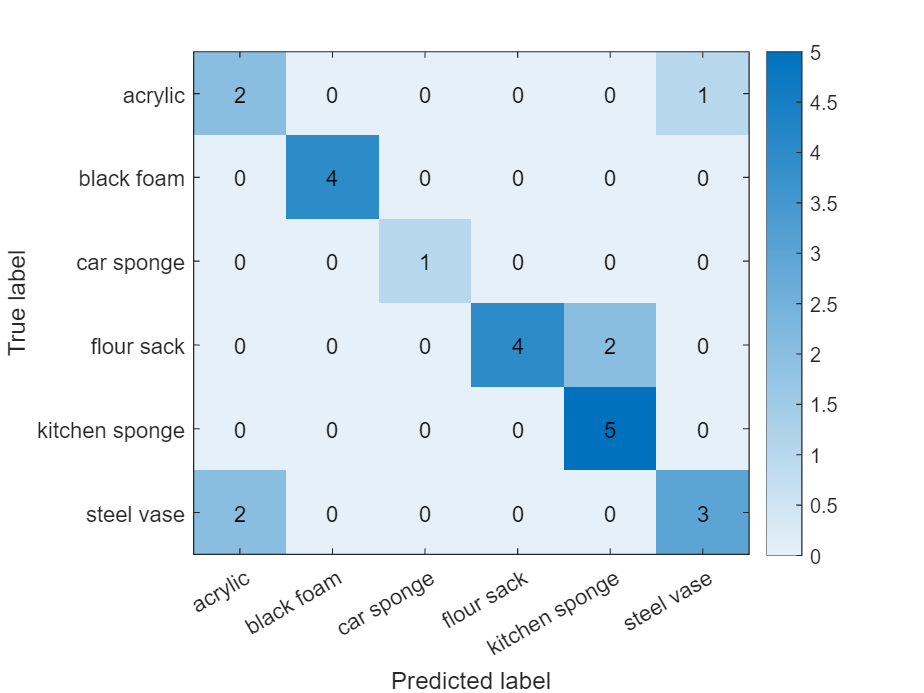

X = projected_ele; % PCA 之后的 electrode data
labels = {'acrylic', 'black foam', 'car sponge', 'flour sack', 'kitchen sponge', 'steel vase'};
repeatedLabels = repmat(labels, 10, 1);
repeatedLabels = repeatedLabels(:); % Convert from matrix to vector
Y = categorical(repeatedLabels);

splitRatio = 0.6; 
totalSamples = size(X, 1);
idx = randperm(totalSamples);

rng("default"); % Set the random number generator to default for reproducibility.
numTrainSamples = floor(splitRatio * totalSamples); % Calculate the number of training samples

% Split the data into training and test sets
XTrain = X(idx(1:numTrainSamples), :);
XTest = X(idx(numTrainSamples+1:end), :);
YTrain = Y(idx(1:numTrainSamples));
YTest = Y(idx(numTrainSamples+1:end));

% Continue with the TreeBagger model training using the training data
Mdl = TreeBagger(200, XTrain, YTrain, 'Method', 'classification', ...
                'OOBPrediction', 'On');


% Visualize one of the trees in the model

% view(Mdl.Trees{1}, 'Mode', 'graph')
% view(Mdl.Trees{2}, 'Mode', 'graph');

[YTestPredicted, scores] = predict(Mdl, XTest);

YTestPredicted = categorical(YTestPredicted);

confusionMatrix = confusionmat(YTest, YTestPredicted);

figure;
confusionMatrix = confusionmat(YTest, YTestPredicted); 
imagesc(confusionMatrix);
colormap(sky); colorbar;
xlabel('Predicted label'); ylabel('True label');

set(gca, 'XTick', 1:length(labels), 'XTickLabel', labels, 'YTick', 1:length(labels), 'YTickLabel', labels);

% 为每个单元格添加文本
numClasses = size(confusionMatrix, 1);
for i = 1:numClasses
    for j = 1:numClasses
        text(j, i, num2str(confusionMatrix(i,j)), ...
            'HorizontalAlignment', 'center', 'Color', 'black');
    end
end
exportgraphics(gcf,'./figures/confusion_matrix_PCA_tree.png','Resolution',300)


% Optionally, calculate additional performance metrics such as accuracy
accuracy = sum(diag(confusionMatrix)) / sum(confusionMatrix, 'all');
disp(['Test Accuracy: ', num2str(accuracy)]);

Test Accuracy: 0.79167


% Decision Tree without PCA
X = F0_Electrodes %F0_Electrodes(:,[7,8,9,10,17]) % F0_Electrodes %F0_PVT % F0_Electrodes;

X =         3346        3671        3679        3618        3683        3535        3165        3312        3232        3346        3129        3618        3667        3553        3659        3569        3553        3673        3623
        3351        3671        3683        3627        3689        3544        3163        3302        3236        3325        3150        3622        3674        3565        3666        3581        3535        3677        3629
        3361        3677        3687        3627        3691        3545        3167        3312        3235        3342        3142        3626        3674        3561        3667        3578        3558        3680        3629
        3360        3683        3690        3625        3691        3541        3181        3332        3259        3379        3147        3633        3677        3560        3667        3578        3581        3681        3631
        3347        3658        3686        3645        3699        3568        

labels = {'acrylic', 'black foam', 'car sponge', 'flour sack', 'kitchen sponge', 'steel vase'};
repeatedLabels = repmat(labels, 10, 1);
repeatedLabels = repeatedLabels(:); % Convert from matrix to vector
Y = categorical(repeatedLabels);

splitRatio = 0.6; 
totalSamples = size(X, 1);
idx = randperm(totalSamples);

rng("default"); % Set the random number generator to default for reproducibility.
numTrainSamples = floor(splitRatio * totalSamples); % Calculate the number of training samples

% Split the data into training and test sets
XTrain = X(idx(1:numTrainSamples), :);
XTest = X(idx(numTrainSamples+1:end), :);
YTrain = Y(idx(1:numTrainSamples));
YTest = Y(idx(numTrainSamples+1:end));

% Continue with the TreeBagger model training using the training data
Mdl = TreeBagger(200, XTrain, YTrain, 'Method', 'classification', ...
                'OOBPrediction', 'On', 'OOBPredictorImportance', 'On');


[YTestPredicted, scores] = predict(Mdl, XTest);

YTestPredicted = categorical(YTestPredicted);

confusionMatrix = confusionmat(YTest, YTestPredicted);

figure;
confusionMatrix = confusionmat(YTest, YTestPredicted); 
imagesc(confusionMatrix);
colormap(sky); colorbar;
xlabel('Predicted label'); ylabel('True label');

set(gca, 'XTick', 1:length(labels), 'XTickLabel', labels, 'YTick', 1:length(labels), 'YTickLabel', labels);

% 为每个单元格添加文本
numClasses = size(confusionMatrix, 1);
for i = 1:numClasses
    for j = 1:numClasses
        text(j, i, num2str(confusionMatrix(i,j)), ...
            'HorizontalAlignment', 'center', 'Color', 'black');
    end
end
exportgraphics(gcf,'./figures/confusion_matrix_baseline_tree.png','Resolution',300)


% Optionally, calculate additional performance metrics such as accuracy
accuracy = sum(diag(confusionMatrix)) / sum(confusionMatrix, 'all');
disp(['Test Accuracy: ', num2str(accuracy)]);

Test Accuracy: 0.75



importance = Mdl.OOBPermutedPredictorDeltaError;

% Optionally, to visualize the importance scores:
figure;
bar(importance);
title('Feature Importance');
xlabel('Predictor Variable');
ylabel('Importance');
xticklabels(Mdl.PredictorNames);
xtickangle(45);